I = imread('man.tiff');
I = double(I);
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T';
% this would pad image with zeros
B = blockproc(I,[8 8],dct);

upper = 0.65;
lower = 0.25;
[Bq q_ref] = myQ(B, upper, lower);
nnz(Bq)

ans = 119892

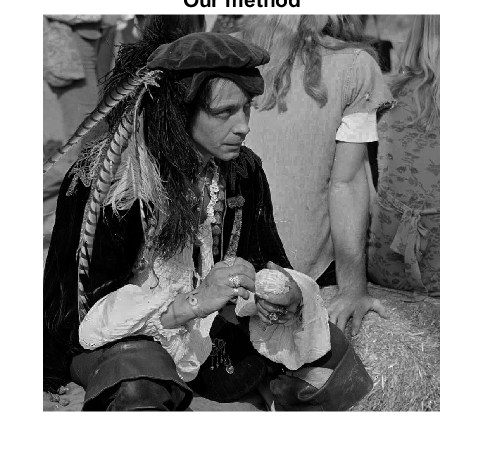

idct = @(block_struct) T' * block_struct.data * T;
Iq = blockproc(Bq,[8 8],idct);
imshow(Iq,[0 255]); truesize; title("Our method");

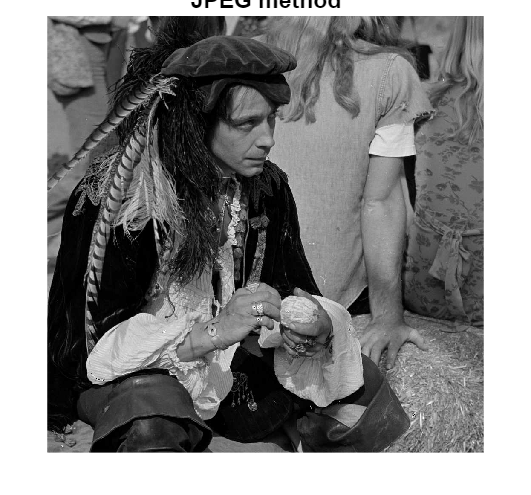

Q_50 = q_factor(50);
aq = blockproc(B,[8 8], @(block_struct) Q_50.* round((block_struct.data) ./ Q_50) );
idct2 = @(block_struct) T' * block_struct.data * T;
Iq2 = blockproc(aq,[8 8],idct2);
imshow(Iq2,[0 255]); truesize; title("JPEG method");

nnz(aq)

ans = 149435

diff1 = log10(norm(I - Iq, 'fro')^2 / norm(I, 'fro')^2)

diff1 = -2.4761

diff12 = log10(norm(I - Iq2, 'fro')^2 / norm(I, 'fro')^2)

diff12 = -2.6481

% we notice that we cannot not just variance as the indicator since for the
% part with light verical or horizontal pattern, it's very sensitive to
% human eye but since the color difference is low, our algorithm
% categorize it as block with low information and thus apply low quality
% factor.

% suggestions: adaptively split the image into different blocks
% such as border detection

% there are too much information by using the variance of the whole image
% probably use soft split / hard split of image

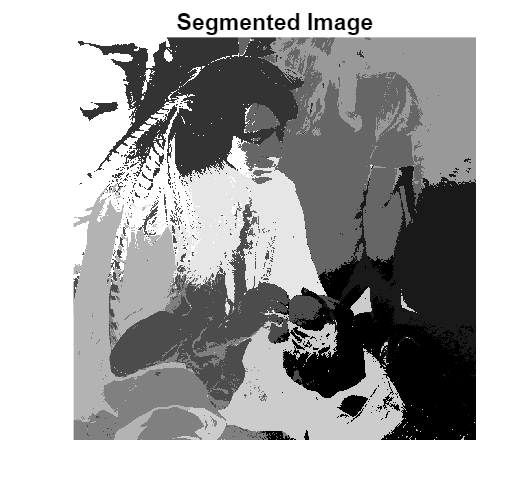

img_gray = I;
% Specify the number of clusters
k = 11;

% Get image dimensions
[rows, cols] = size(img_gray);
% Prepare data for clustering: include pixel intensity and spatial coordinates
[X, Y] = meshgrid(1:cols, 1:rows);
X = X(:);
Y = Y(:);
intensities = double(reshape(img_gray, [], 1));

% Combine the data (adjust weight of coordinates to tune spatial coherence)
weight = 0.2;  % Adjust this parameter to balance intensity vs. spatial importance
data = [intensities, weight * X, weight * Y];

% Perform k-means clustering
[idx, C] = kmeans(data, k);

% Reshape the clustering result back to the image size
clustered_image = reshape(idx, size(I));

imagesc(clustered_image);  % Use imagesc to display the clustered labels
colormap('gray');  % Display in grayscale
title('Segmented Image');
axis equal tight off;  % Adjust axis properties for better display



% probably within each section, kind of genereate a historgram of them
% and count number of bins larger than certain amount
% to detect if there's a pattern
% if there is, use a higher quality factor

% on the border of two section, always use a default quality factor

% Silhouette Analysis  could be used to auto choosing number segements in
% an image

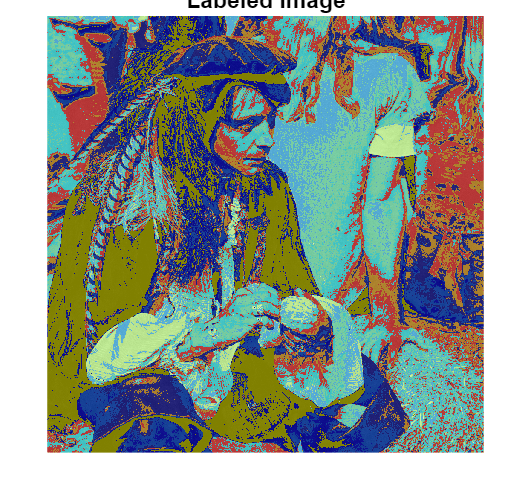

% Doesn't work well

% II = uint8(img_gray);
% L = imsegkmeans(II,10);
% B = labeloverlay(II,L);
% imshow(B)
% title("Labeled Image")

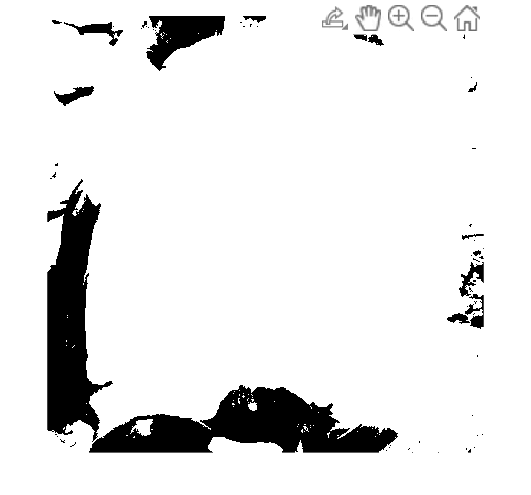

II = uint8(img_gray);
mask = zeros(size(II));
mask(25:end-25,25:end-25) = 1;
bw = activecontour(II,mask,500);
imshow(bw)